**1.** Implementati o rutina pentru calculul valorilor polinomului de interpolare Hermite cu noduri duble, dandu-se punctele in care se face evaluarea, nodurile, valorile functiei si ale derivatei in noduri.

A se vedea functia `interpolareHermite` din josul documentului.

**2.** Reprezentati pe acelasi grafic f si polinomul sau de interpolare Hermite.

x = linspace(0,5,4);
f = sin(x)

f =          0    0.9954   -0.1906   -0.9589


df = cos(x)

df =     1.0000   -0.0957   -0.9817    0.2837



xx = linspace(-0.5,5.5,100);

yp = interpolareHermite(x, f, df, xx);

q =          0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0
    0.9954    0.5972   -0.2417         0         0         0         0         0         0         0
    0.9954   -0.0957   -0.4158   -0.1045         0         0         0         0         0         0
   -0.1906   -0.7116   -0.3695    0.0139    0.0355         0         0         0         0         0
   -0.1906   -0.9817   -0.1621    0.1245    0.0332   -0.0007         0         0         0         0
   -0.9589   -0.4610    0.3124    0.1423    0.0054   -0.0056   -0.0010         0         0         0
   -0.9589    0.2837    0.4468    0.0806   -0.0185   -0.0072   -0.0003    0.0001         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0       

yt = sin(xx);

err = abs(yp - yt)

err =     0.8966    0.8006    0.7008    0.5972    0.4901    0.3797    0.2661    0.1495    0.0302    0.0007    0.0035    0.0084    0.0151    0.0233    0.0327    0.0431    0.0542    0.0658    0.0775    0.0890    0.1002    0.1106    0.1201    0.1283    0.1350    0.1398    0.1425    0.1428    0.1404    0.1351    0.1265    0.1143    0.0984    0.0784    0.0540    0.0250    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0004    0.0006    0.0009    0.0012    0.0016    0.0020    0.0025    0.0030


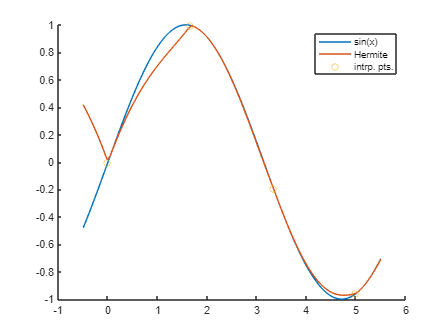


clf
hold on
plot(xx, yt)
plot(xx, yp)
scatter(x,f)
legend(["sin(x)","Hermite","intrp. pts."])
hold off

**3.** Scrieti o rutina care reprezinta grafic o cubica parametrica Hermite (o curba care trece prin doua puncte date si are in acele puncte tangente)

x = [-3 3]; % x^2+x
f = [6 12];
df = [-5 7];

xx = linspace(-4,4,50);

yp = interpolareHermite(x, f, df, xx);

q =      6     0     0     0     0     0
     6    -5     0     0     0     0
    12     1     1     0     0     0
    12     7     1     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


yt = xx.*xx+xx;

err = abs(yp - yt)

err =    10.0000    8.3673    6.7347    5.1020    3.4694    1.8367    0.2041    0.0000    0.0000         0         0    0.0000    0.0000    0.0000    0.0000         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000         0    0.0000         0


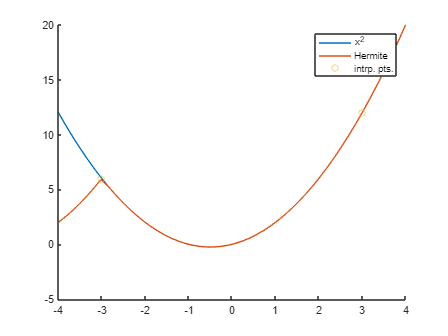


clf
hold on
plot(xx, yt)
plot(xx, yp)
scatter(x,f)
legend(["x^2","Hermite","intrp. pts."])
hold off

function [ res ] = interpolareHermite(x, f, fd, point )
% aproximeaza x folosind interpolarea Hermite
    % initializare
    [rows, m] = size(x);
    q = zeros(2 * m + 2, 2 * m + 2);
    z = zeros(2 * m + 2);
    
    % z contine x0 x0 x1 x1 x2 x2 ...
    % Q contine f(x0) f(x0) f(x1) x(x1) ...
    %           - f'(x0) f[x1,x0] f'(x1) f[x2,x1] ...
    for i = 1 : m
        % p2
        z(2 * i - 1) = x(i);
        z(2 * i) = x(i);
        q(2 * i - 1, 1) = f(i);
        q(2 * i, 1) = f(i);
        q(2 * i, 2) = fd(i);
        % p3
        if i ~= 1
            q(2*i-1,2)=(q(2*i-1,1)-q(2*i-2,1))/(z(2*i-1)-z(2*i-2));
        end
    end
    
    % se completeaza diferentele divizate
    for i = 3 : 2 * m
       for j = 3 : i
          q(i,j)=(q(i,j-1)-q(i-1,j-1))/(z(i)-z(i-j+1)); 
       end
    end
    q
    % calc p(i)
    n = size(point, 2);
    s = ones(1,n) * 1;
    p = ones(1,n) * q(1, 1);
    for i = 2 : 2 * m
       a = abs(x(floor(i/2)) - point);       
       s = s .* a;
       prev = p;
       p = p + s .* q(i,i);
       res = p;       
       if abs(prev-p)<1e-5
          break 
       end
    end
end